## B

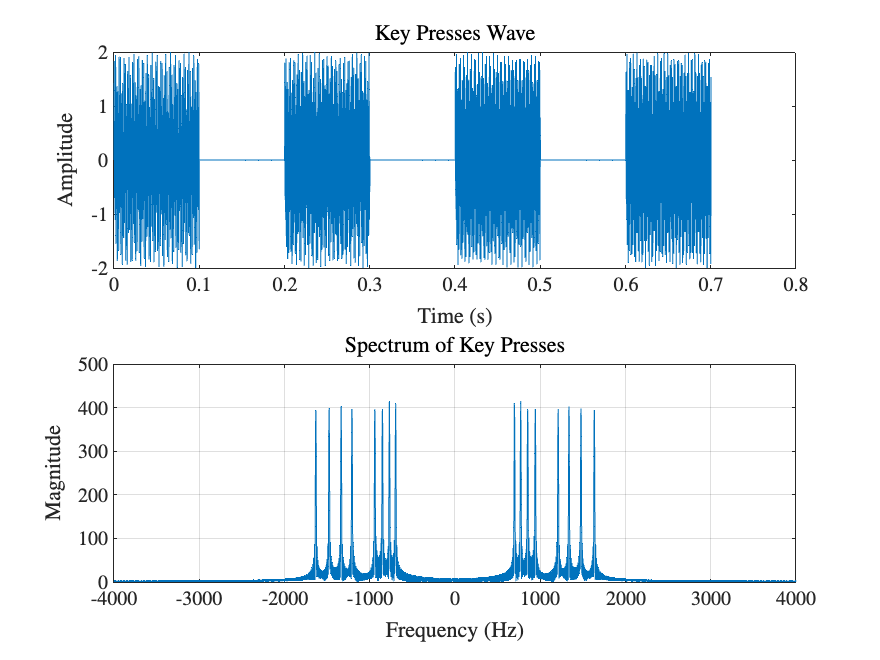

resolution = 1200;
fs = 8000;
duration = 0.1;
gap = 0.1;

[t_total,z] = generate_wave({"1","5","9","D"},fs,duration,gap);
figure;
subplot(2,1,1)
plot(t_total, z);
title("Key Presses Wave");
xlabel("Time (s)");
ylabel("Amplitude");

key_spectra = fft(z);

subplot(2,1,2)
f_output = linspace(-fs/2, fs/2, length(key_spectra));
plot(f_output, (abs(fftshift(key_spectra))));
grid on
title('Spectrum of Key Presses');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


% exportgraphics(gcf, 'TeX/images/4B.png', 'Resolution', resolution);